# **1 How finite should it be?**

### ***1.1 Like a hot knife through a Butterworth***

%Passband and stopband in normalized frequency
clear all;
wp = [0.2 0.3];
ws = [0.1 0.4];
Rp = 2; %maximum ripple gain
Gs = 100; %stopband attenuation
[n_ord, Wn] = buttord(wp, ws, Rp, Gs) %Minimum required order and cutoff frequencies

n_ord = 12

Wn =     0.1986    0.3020


[B, A] = butter(n_ord, Wn) %Polynomial coefficients

B = 	1.0e+-7 *

    0.0011         0   -0.0129         0    0.0710         0   -0.2367         0    0.5325         0   -0.8519         0    0.9939         0   -0.8519         0    0.5325         0   -0.2367         0    0.0710         0   -0.0129         0    0.0011


A = 	1.0e+05 *

    0.0000   -0.0002    0.0012   -0.0060    0.0226   -0.0667    0.1606   -0.3228    0.5510   -0.8076    1.0249   -1.1317    1.0908   -0.9186    0.6751   -0.4318    0.2391   -0.1137    0.0459   -0.0155    0.0043   -0.0009    0.0001   -0.0000    0.0000


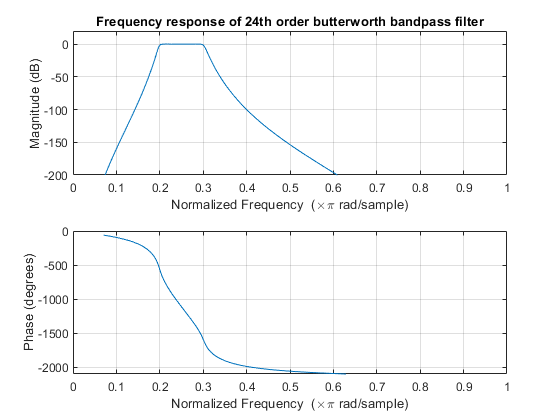


%frequency response
figure(1)
freqz(B,A)
ylim([-200,20]);
title('Frequency response of 24th order butterworth bandpass filter')

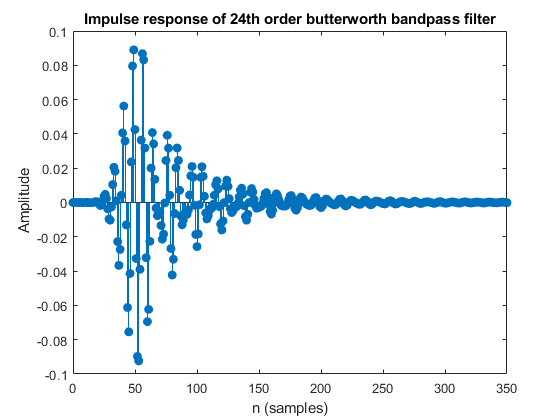


figure(2)
impz(B,A)
title('Impulse response of 24th order butterworth bandpass filter')
xlim([0,350])

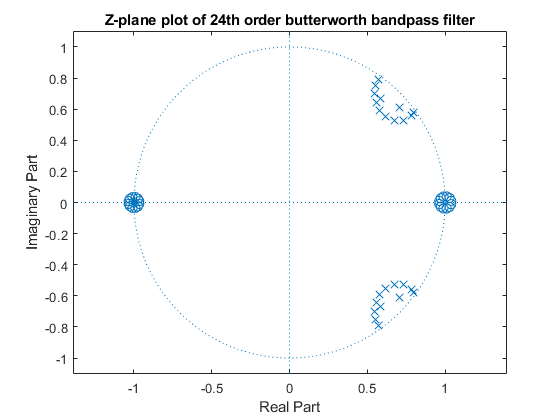


figure(3)
zplane(B,A)
title('Z-plane plot of 24th order butterworth bandpass filter')


%Transfer function:
%filt(B,A) 

%Loading impulse response into response and sample vectors
[h, n] = impz(B,A);

The effective length of the impulse response is defined as the length at which the response has values above 10% of its maximum.

%Finding the local peaks of the response
[pks, idx] = findpeaks(abs(h));
%Finding index at which the response decays below 10% of maximum value
transpose(find(pks < (0.1 * max(h)))) %transposed to show more values below

ans =      1     2     3     4     5     6     7    18    24    32    33    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73


Observing the plot of the impulse response, the peaks seem to decay to below 10% of maximum value at $n\approx 130$.

The *findpeaks*-function seems to only find peaks below the threshold after about index 35 of the peak-vector.

The original index of the *h*-vector at which this peak occurs is:

idx(35)

ans = 145

By observation of the impulse response plot around this number of samples, the window can be closed at:

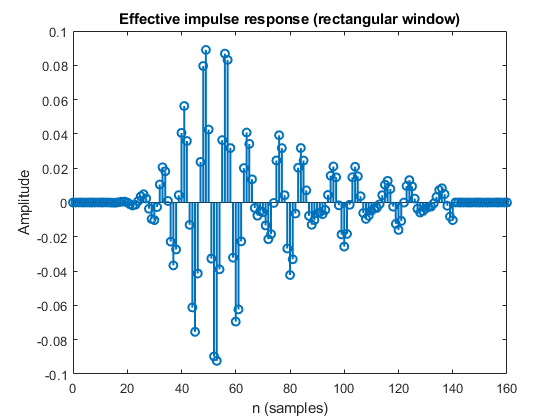

n_low = 142;
%Creating rect-window
rect = [ones(1, n_low-1) zeros(1, length(h)-(n_low-1))];
h_eff_rect = transpose(h) .* rect;

%Creating Hann-window
whann = [transpose(hann(n_low)) zeros(1, length(h)-n_low)];
h_eff_hann = transpose(h) .* whann;

figure(4)
stem(n,h_eff_rect,'LineWidth',1.5)
title('Effective impulse response (rectangular window)')
xlabel('n (samples)')
ylabel('Amplitude')
ylim([-0.1,0.1])
xlim([0,160])

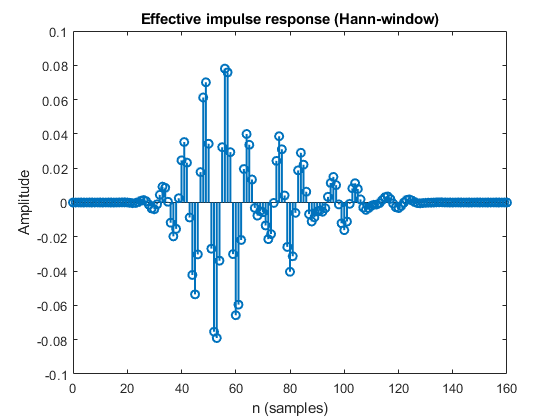

figure(5)
stem(n,h_eff_hann,'LineWidth',1.5)
title('Effective impulse response (Hann-window)')
xlabel('n (samples)')
ylabel('Amplitude')
ylim([-0.1,0.1])
xlim([0,160])

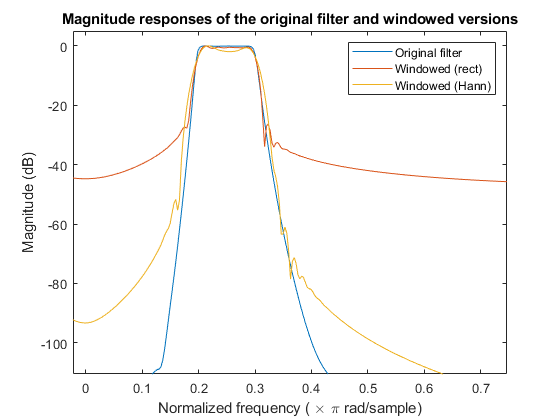

[Y,~] = make_spectrum(h, 44100);
[Y_eff_rect,~] = make_spectrum(h_eff_rect, 44100);
[Y_eff_hann,freq_eff] = make_spectrum(h_eff_hann, 44100);

%We wanna plot in normalized frequency
freq_norm = freq_eff/(44100/2);

figure(6)
plot(freq_norm, 20*log10(abs(Y)/max(abs(Y))))
hold on
plot(freq_norm, 20*log10(abs(Y_eff_rect)/max(abs(Y_eff_rect))))
plot(freq_norm, 20*log10(abs(Y_eff_hann)/max(abs(Y_eff_hann))))
hold off
xlim([0,0.7])
ylim([-100,5])
xlabel('Normalized frequency ( \times \pi rad/sample)')
ylabel('Magnitude (dB)')
legend('Original filter','Windowed (rect)','Windowed (Hann)')
title('Magnitude responses of the original filter and windowed versions')

The effects of the original magnitude response being convolved with the spectra of the rect- and Hann-window functions can be seen as the oscillations in the frequency domain.

The Hann-window can be seen the better follow the attenuation dips of the original designed filter and is closer to the specification of -100 dB stopband gain than the rect-windowed version.

The rect-windowed version does however have smaller passband ripples.

*Cut to 75, 60, 40 and 10% of effective length*:

% threshold_values = [0.75, 0.60, 0.40, 0.10] * 0.1 * max(h)
% for i = 1:4
%     transpose(find(pks < threshold_values(i)))
% end
% %original indices of peak values below threshold
% idx([39, 39, 43, 59])
% % %Small corrections from observations in plot of original impulse response:
% n_lows = [162, 162, 182, 258];

%Cutting the length to 75%, 60%, 40% and 10%
n_lows = [floor(0.75*n_low) floor(0.60*n_low) floor(0.40*n_low) floor(0.10*n_low)];

%Creating the rect- and Hann-windows for the four new thresholds and windowing
rects = zeros(4, length(h));
whanns = zeros(4, length(h));
h_eff_rects = zeros(4, length(h));
h_eff_hanns = zeros(4, length(h));
Y_eff_rects = zeros(4, length(h));
Y_eff_hanns = zeros(4, length(h));
for k = 1:4
    rects(k,:) = [ones(1, n_lows(k)-1) zeros(1, length(h)-(n_lows(k)-1))];
    whanns(k,:) = [transpose(hann(n_lows(k))) zeros(1, length(h)-n_lows(k))];
    %windowing
    h_eff_rects(k,:) = transpose(h) .* rects(k,:);
    h_eff_hanns(k,:) = transpose(h) .* whanns(k,:);   
    %spectra
    [Y_eff_rects(k,:),~] = make_spectrum(h_eff_rects(k,:), 44100);
    [Y_eff_hanns(k,:),~] = make_spectrum(h_eff_hanns(k,:), 44100);
end

*Plotting the frequency responses for the new threshold values:*

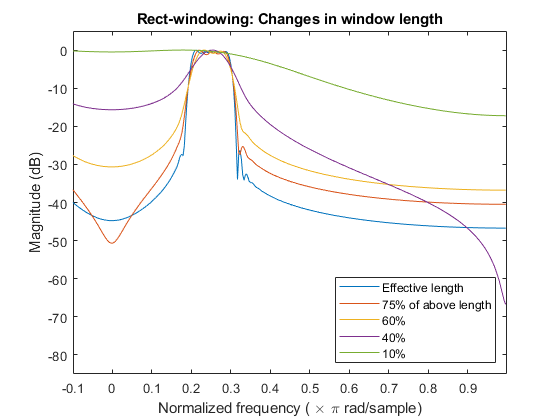


figure(7)
plot(freq_norm, 20*log10(abs(Y_eff_rect)/max(abs(Y_eff_rect))))
hold on
plot(freq_norm, 20*log10(abs(Y_eff_rects(1,:))/max(abs(Y_eff_rects(1,:)))))
plot(freq_norm, 20*log10(abs(Y_eff_rects(2,:))/max(abs(Y_eff_rects(2,:)))))
plot(freq_norm, 20*log10(abs(Y_eff_rects(3,:))/max(abs(Y_eff_rects(3,:)))))
plot(freq_norm, 20*log10(abs(Y_eff_rects(4,:))/max(abs(Y_eff_rects(4,:)))))
hold off
xlim([0,1])
ylim([-85,5])
xlabel('Normalized frequency ( \times \pi rad/sample)')
ylabel('Magnitude (dB)')
legend('Effective length','75% of above length','60%','40%','10%','Location','southeast')
title('Rect-windowing: Changes in window length')

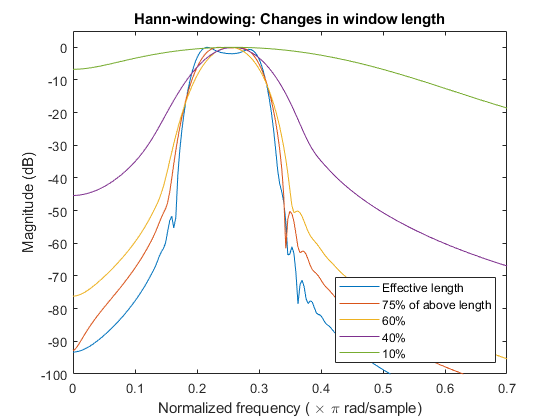

figure(8)
plot(freq_norm, 20*log10(abs(Y_eff_hann)/max(abs(Y_eff_hann))))
hold on
plot(freq_norm, 20*log10(abs(Y_eff_hanns(1,:))/max(abs(Y_eff_hanns(1,:)))))
plot(freq_norm, 20*log10(abs(Y_eff_hanns(2,:))/max(abs(Y_eff_hanns(2,:)))))
plot(freq_norm, 20*log10(abs(Y_eff_hanns(3,:))/max(abs(Y_eff_hanns(3,:)))))
plot(freq_norm, 20*log10(abs(Y_eff_hanns(4,:))/max(abs(Y_eff_hanns(4,:)))))
hold off
xlim([0,0.7])
ylim([-100,5])
xlabel('Normalized frequency ( \times \pi rad/sample)')
ylabel('Magnitude (dB)')
legend('Effective length','75% of above length','60%','40%','10%','Location','southeast')
title('Hann-windowing: Changes in window length')

### ***1.2 Shorter and shorter***

fc = 5000;
l = 601; %known length of impulse response

%Cutoff frequency at 1/3 normalised frequency
%Cutoff is also known to be 5 kHz
f_N = 3 * fc;
fs = 2 * f_N;

%the frequency resolution is given by 1/T (length of the signal)
Ts = 1/fs;
T = Ts * l;
delta_f = 1/T

delta_f = 49.9168

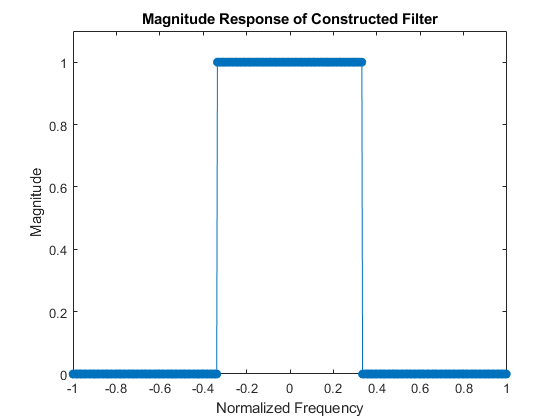

w = -fs/2:delta_f:(fs/2 - delta_f); %discrete frequency vector

high = ones(1, 100);
low = zeros(1, 200);

Y = [low high 1 high low];

figure(9)
plot(w/f_N,Y,['-o'])

xlabel('Normalized Frequency')
ylabel('Magnitude')
title('Magnitude Response of Constructed Filter')
ylim([0,1.1])
xlim([-1,1])

h = fftshift(ifft(ifftshift(Y))) %getting impulse response... needs to be shifted with fftshift afterwards

h =     0.0014   -0.0000   -0.0014   -0.0014    0.0000    0.0015    0.0014   -0.0000   -0.0015   -0.0014    0.0001    0.0015    0.0014   -0.0001   -0.0015   -0.0014    0.0001    0.0015    0.0014   -0.0001   -0.0015   -0.0014    0.0001    0.0015    0.0014   -0.0001   -0.0015   -0.0014    0.0002    0.0015    0.0014   -0.0002   -0.0015   -0.0014    0.0002    0.0016    0.0013   -0.0002   -0.0016   -0.0013    0.0002    0.0016    0.0013   -0.0003   -0.0016   -0.0013    0.0003    0.0016    0.0013   -0.0003


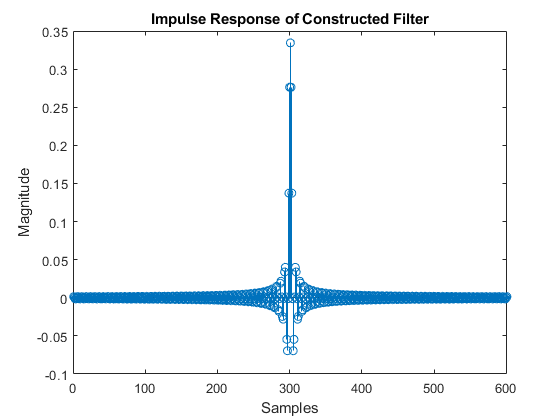

figure(10)
stem(h)
xlim([0,601])
xlabel('Samples')
ylabel('Magnitude')
title('Impulse Response of Constructed Filter')

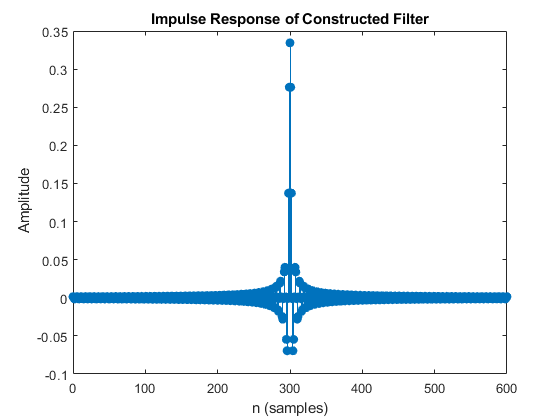


% do an impz plot
impz(h,1)
title('Impulse Response of Constructed Filter')

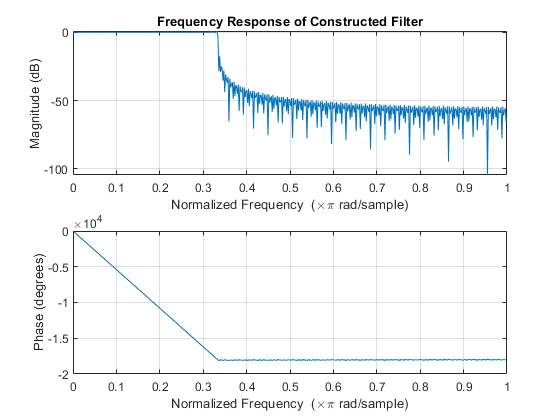


% do a freqz plot
freqz(h,1)
title('Frequency Response of Constructed Filter')

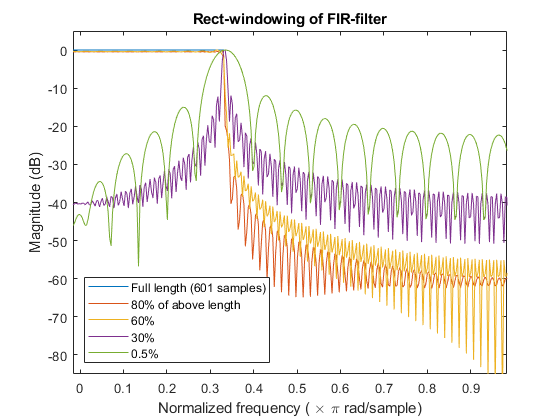


%Windowing stepwise:
windows = floor([0.8*l 0.6*l 0.3*l 0.05*l]);

%Creating the rect-windows for the four new thresholds and windowing
rects = zeros(4, l);
Y_window = zeros(4, l);
h_window = zeros(4, l);

for k = 1:4
    rects(k,:) = [ones(1, windows(k)) zeros(1, l - windows(k))];
    h_window(k,:) = h .* rects(k,:);  
    %spectra
    [Y_window(k,:),~] = make_spectrum(h_window(k,:), fs);
end

figure(11)
plot(w/f_N, 20*log10(abs(Y)/max(abs(Y))))
hold on
plot(w/f_N, 20*log10(abs(Y_window(1,:))/max(abs(Y_window(1,:)))))
plot(w/f_N, 20*log10(abs(Y_window(2,:))/max(abs(Y_window(2,:)))))
plot(w/f_N, 20*log10(abs(Y_window(3,:))/max(abs(Y_window(3,:)))))
plot(w/f_N, 20*log10(abs(Y_window(4,:))/max(abs(Y_window(4,:)))))
hold off
xlim([0,1])
ylim([-85,5])
xlabel('Normalized frequency ( \times \pi rad/sample)')
ylabel('Magnitude (dB)')
legend('Full length (601 samples)','80% of above length','60%','30%','0.5%','Location','southwest')
title('Rect-windowing of FIR-filter')

The magnitude response shows greater oscillations and tails as the impulse response is cut more. 

As the impulse response is cut beyond 50%, too much information is lost and it no longer shows a low-pass filter characteristic and resembles a band-pass filter.

It should therefore not be cut beyond at least 60% for it to perform as a low-pass filter.

# **2 An equalizer - without buttons**

### ***2.1 Bass and treble***

% Normalized cutoff frequencies
w_c = [0.3, 0.7]; 

% Passband gain in dB
Gp_dB = 30;
% Length of filter (order + 1)
L = 201;

Note for the defined function:

Finding frequency resolution in normalized frequency:


$$\Delta f=\frac{1}{T}=\frac{1}{\frac{1}{f_s }\cdot n}$$


Normalized with respect to Nyquist frequency:

 
$$\frac{\frac{1}{\frac{1}{f_s }\cdot n}}{f_N }=\frac{1}{\frac{f_N }{f_s }\cdot n}=\frac{1}{\frac{f_N }{2\cdot f_N }\cdot n}=\frac{2}{n}=\Delta \omega_{\textrm{norm}}$$
 

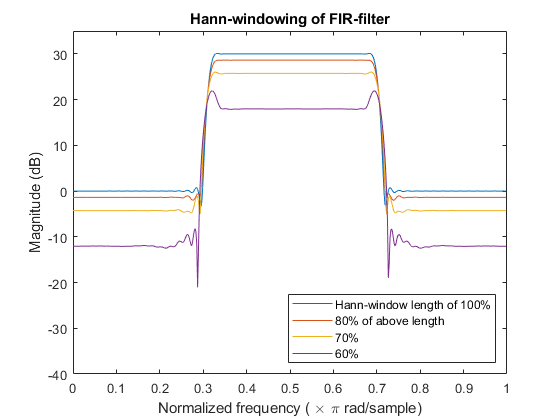

[h_10, w_norm] = freqz(fir_bandpass(w_c, Gp_dB, L, 1));
[h_08, ~] = freqz(fir_bandpass(w_c, Gp_dB, L, 0.8));
[h_07, ~] = freqz(fir_bandpass(w_c, Gp_dB, L, 0.7));
[h_06, ~] = freqz(fir_bandpass(w_c, Gp_dB, L, 0.6));

w_norm = w_norm/pi;

figure(13)
plot(w_norm, 20*log10(abs(h_10)))
hold on
plot(w_norm, 20*log10(abs(h_08)))
plot(w_norm, 20*log10(abs(h_07)))
plot(w_norm, 20*log10(abs(h_06)))
hold off
xlim([0,1])
ylim([-40,35])
xlabel('Normalized frequency ( \times \pi rad/sample)')
ylabel('Magnitude (dB)')
legend('Hann-window length of 100%','80% of above length','70%','60%','Location','southeast')
title('Hann-windowing of FIR-filter')

Best compromise between speed and precision seems to be around 70% (note the offsets of the filters - they are quite well aligned magnitude-wise except for 60% windowing)

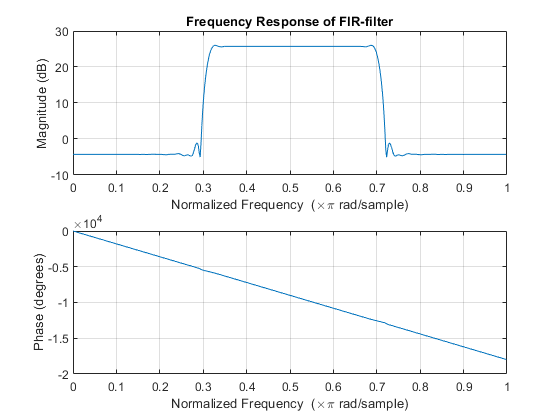

freqz(fir_bandpass(w_c, Gp_dB, L, 0.7))
title('Frequency Response of FIR-filter')

Testing on Sax12.wav:

% Normalized cutoff frequencies

%bass
w_c = [20/22050, 500/22050]; 

%mid-range
% w_c = [500/22050, 4000/22050];

%treble
% w_c = [5000/22050, 20000/22050];

% Passband gain in dB
Gp_dB = 30;
% Length of filter (order + 1)
L = 501;

[B,A] = fir_bandpass(w_c, Gp_dB, L, 0.7);

[music, fs_loaded] = audioread([pwd filesep 'scrambled_eggs_5s.wav']);

% sound(sax/max(sax), fs_loaded)
music_filtered = filter(B,A,music);

% Unnormalized output - warning may be loud or have a lot of clipping depending on gain setting!
% sound(music_filtered, fs_loaded)

% Normalized output to avoid clipping:
sound(rescale(music_filtered,-1,1), fs_loaded)

%Current cutoff frequencies at a sampling rate of 44100 Hz
w_c * 22050

ans =     20   500


clear sound